if ~exist('data/chap09', 'dir')
    gunzip('https://github.com/sp-au-mu-nl/SpeechComm/raw/refs/heads/main/data/chap09.zip','data')
    unzip('data/chap09.zip', 'data/chap09/')
end

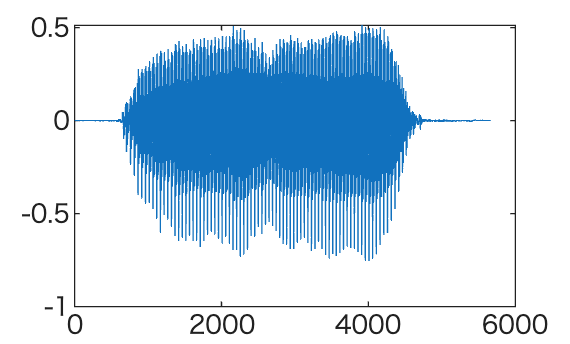

[yA, sr] = audioread('data/chap09/a8k.wav');
plot(yA)

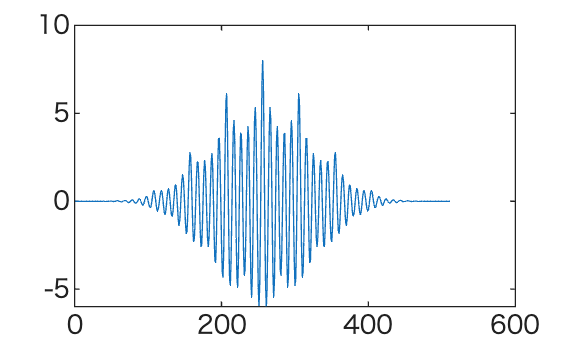

nLag = 256;
ySegment = yA(2000+(1:nLag)).*hann(nLag);
ac = xcorr(ySegment);
plot(ac)

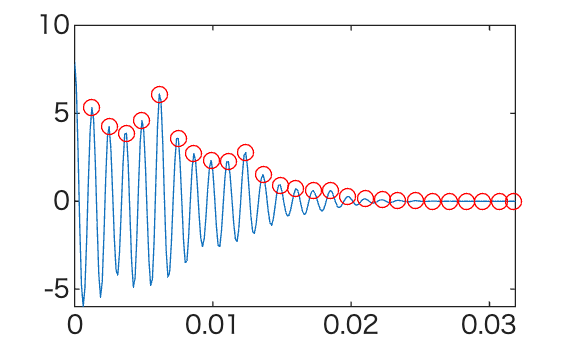

iCenter = length(ySegment);
x = (0:iCenter-1)/sr;
acRight = ac(iCenter:end);
iPeaks = find(islocalmax(acRight));
plot(x, acRight); hold on
plot(x(iPeaks), acRight(iPeaks), 'ro'); hold off

[~, iMax] = max(acRight(iPeaks));
1/x(iPeaks(iMax))

ans = 163.2653

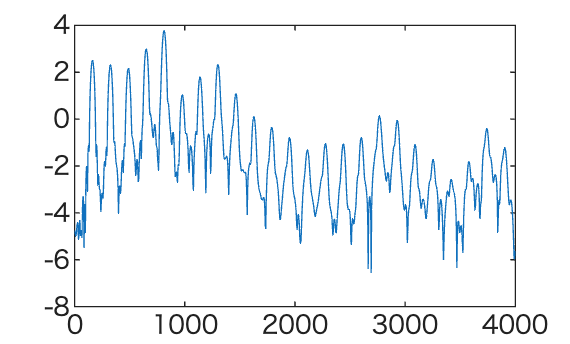

nFrame = 512; nFFT = 2048;
ySegment = yA(2000+(1:nFrame)).*hann(nFrame);
logS = log(abs(fft(ySegment, nFFT)));
nFreq = nFFT/2+1;
frequency = linspace(0, sr/2, nFreq);
plot(frequency, logS(1:nFreq));

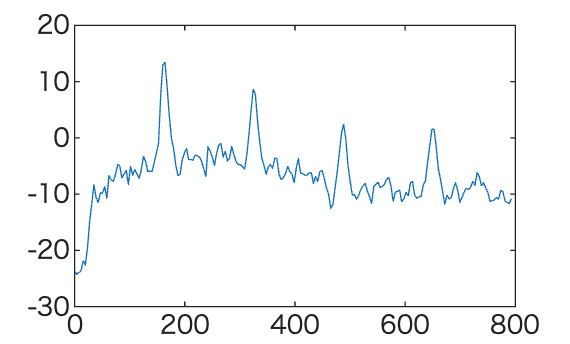

K = 5;
iUpper = round(nFFT/2/K)-1;
P = logS(1:iUpper);
for r = 2:K
    index = 1:r:iUpper*r;
    P = P+logS(index);
end
plot(frequency(1:iUpper), P)

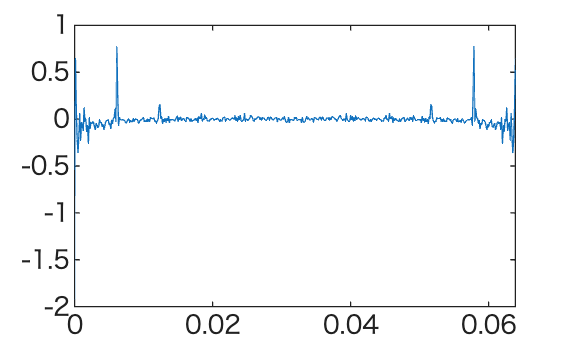

nFFT = 512;
cepstrum = ifft(log(abs(fft(ySegment, nFFT))));
t = (0:(length(cepstrum)-1))/sr;
plot(t, cepstrum)